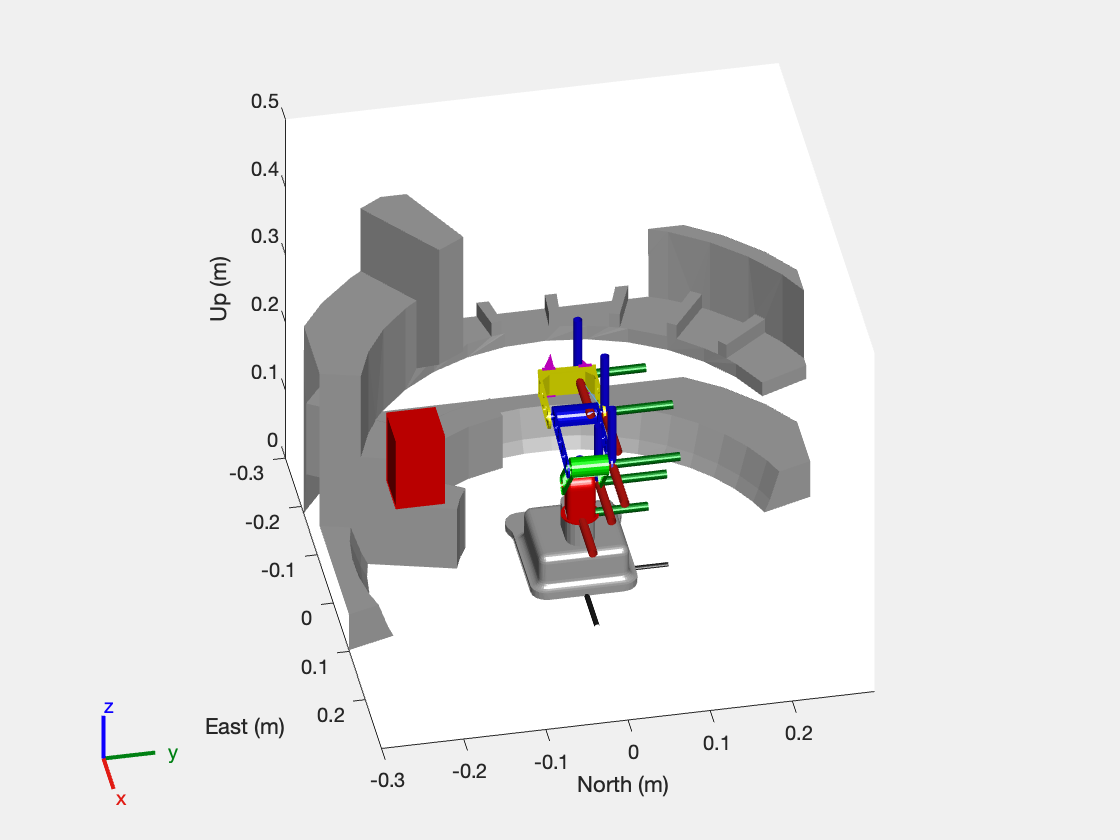

% Perform Pick and Place in Robot Scenario
clc
clear

% Create a robotScenario object.
scenario = robotScenario(UpdateRate=10, StopTime=10);

% Load in the correct file directory
addpath("/Users/louieburns/Library/CloudStorage/OneDrive-UniversityofLeeds/Robotics Coursework/URDFs/Robot_URDF/urdf")
savepath

% Create a rigidBodyTree object of the Franka Emika Panda manipulator using loadrobot.
robotRBT = importrobot("Robot_URDF.urdf");

% Create a rigidBodyTree-based robotPlatform object using the manipulator model.
robot = robotPlatform("Manipulator", scenario, RigidBodyTree=robotRBT);

% Create a non-rigidBodyTree-based robotPlatform object of a box to manipulate.
box1_pos = [0 -0.2 0.2];
box = robotPlatform("Box", scenario, Collision="mesh", InitialBasePosition=box1_pos);
updateMesh(box, "Cuboid", Collision="mesh", Size=[0.06 0.06 0.1])

% Visualize the scenario.
ax = show3D(scenario, Collisions="off");
view(79,36)
axis equal
axis manual
xlim([-0.3 0.3]);
ylim([-0.3 0.3]);
zlim([0 0.5]);
light

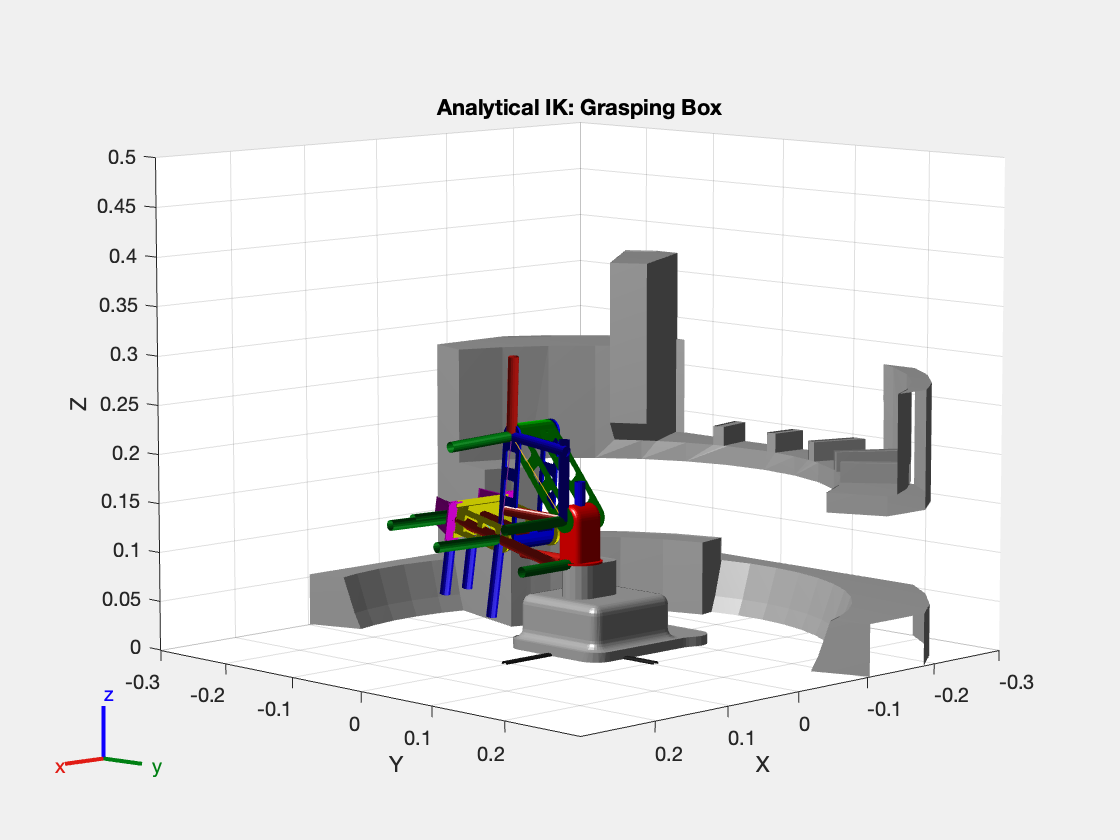


% Inverse Kinematics
function q = analyticalIK(x, y, z)
    L1 = 0.107;
    L2 = 0.109;
    L3 = 0.072;
    L4 = 0.102;
    baseHeight = 0.09;

    theta1 = atan2(y, x);
    r = sqrt(x^2 + y^2);
    z = z - baseHeight;
    r = r - L4;

    D = (r^2 + z^2 - L1^2 - L2^2) / (2 * L1 * L2);
    if abs(D) > 1
        error("Position unreachable");
    end
    theta3 = atan2(sqrt(1 - D^2), D);

    phi = atan2(z, r);
    psi = atan2(L2 * sin(theta3), L1 + L2 * cos(theta3));
    theta2 = phi - psi;

    theta4 = - (theta2 + theta3);

    q = [theta1, theta2, theta3, theta4];
end

% Target Position (position of the box)
targetPos = [box1_pos(1), -box1_pos(2), box1_pos(3)];
q = analyticalIK(targetPos(1), targetPos(2), targetPos(3));

% Get initial and target joint configurations
initialConfig = homeConfiguration(robotRBT);
targetConfig = initialConfig;
targetConfig(1).JointPosition = q(1);
targetConfig(2).JointPosition = q(2);
targetConfig(3).JointPosition = q(3);
targetConfig(4).JointPosition = q(4);
targetConfig(5).JointPosition = -0.015;
targetConfig(6).JointPosition =  0.015;

% Improved Midpoint (arc over robot to avoid collision)
midZ = 0.25;       % elevated height
midX = targetPos(1) + 0.1;  % shift forward to curve over
midY = targetPos(2);        % same Y
midPos = [midX, midY, midZ];
qMid = analyticalIK(midPos(1), midPos(2), midPos(3));

midConfig = initialConfig;
midConfig(1).JointPosition = qMid(1);
midConfig(2).JointPosition = qMid(2);
midConfig(3).JointPosition = qMid(3);
midConfig(4).JointPosition = qMid(4);
midConfig(5).JointPosition = -0.015;
midConfig(6).JointPosition =  0.015;

% Function to interpolate between two configs with quintic timing
function interpolateConfigs(robotRBT, configStart, configEnd, steps)
    for t = linspace(0, 1, steps)
        s = 6*t^5 - 15*t^4 + 10*t^3;
        interpConfig = configStart;
        for i = 1:length(configStart)
            interpConfig(i).JointPosition = (1 - s) * configStart(i).JointPosition + s * configEnd(i).JointPosition;
        end
        show(robotRBT, interpConfig, FastUpdate=true, PreservePlot=false);
        title("Analytical IK: Grasping Box");
        axis equal
        axis manual
        xlim([-0.3 0.3]);
        ylim([-0.3 0.3]);
        zlim([0 0.5]);
        drawnow;
    end
end

% Execute in 2 stages to go up and over robot
steps = 100;
interpolateConfigs(robotRBT, initialConfig, midConfig, steps);
interpolateConfigs(robotRBT, midConfig, targetConfig, steps);